# Linear Control Design II - Group Work Problem Module 19

## **Part A - **Time Dependent Discrete LQR Control: first order system.

The purpose of this exercise is to illustrate in detail what how a time dependent optimal controller is designed for a simple first order system. Consider a discrete time controller for a system given by:


$$x(k+1)=0.3679 \: x(k) + 0.6321 \: u(k)$$


with the boundary condition that $x(0)=1$. For this system find an optimal controller to minimizes the performance index:


$$J = \frac{1}{2}\left[ x(10)^2 \right] + \frac{1}{2} \sum\limits_{k=0}^{9}\left[ x^2(k) + u^2(k) \right]$$


Note that in this example the weighting matrices have been selected to be:


$$\mathbf{S}=1 \qquad \mathbf{R_1}=1 \qquad \mathbf{R_2}=1$$


The minimum value of the index $J$ is also to be determined.

To solve this problem it is required that it be solved backwards from the final time. The boundary condition on the matrix $\mathbf{P}(N)$is:


$$\mathbf{P}(N) = \mathbf{S} \Rightarrow \mathbf{P}(N) = \mathbf{P}(10)=\mathbf{S}=1$$


The Riccati equation has to be solved in order to calculate the time varying optimal gain. In this case it can be written as:


$$\mathbf{P}(k) = 1+0.3679 \cdot \mathbf{P}(k+1)\left[ 1+0.6321 \cdot 1 \cdot 0.6321 \cdot \mathbf{P}(k+1) \right]^{-1}0.3679$$


which can be simplified to:


$$\mathbf{P}(k) = 1+0.1354 \cdot \mathbf{P}(k+1)\left[ 1+0.3996 \cdot \mathbf{P}(k+1) \right]^{-1}$$


One can now calculate backwards to the desired start time:

 
$$\mathbf{P}(9) = 1+0.1354 \cdot 1 \cdot \left[ 1+0.3996\cdot 1 \right]^{-1} = 1.0967\\ \mathbf{P}(8) = \ldots$$


**Problem 1 **Write a Matlab program to carry though these calculations to find $\mathbf{P}(0)$. What is especially noticeable about the values of $\mathbf{P}(k)$ during this process? What is the steady state value of $\mathbf{P}(k)$ i.e. $\mathbf{P}_{SS}$? Note that this value must be positive as $\mathbf{P}(k)$must be positive definite.

Calculate now the feedback gains necessary (at the different sampling times) to accomplish the desired control.

**Solution:**

% Your solution goes here:
F = 0.3679;
G = 0.6321;
S = 1;
R1 = 1;
R2 = 1;

P = zeros(1,11);
P(11) = S;
for i = 10:-1:1
    P(i) = R1+F*P(i+1)*(1+G/R2*G*P(i+1))^-1*F;
end
disp(P)

       1.1037       1.1037       1.1037       1.1037       1.1037       1.1037       1.1037       1.1036       1.1032       1.0967            1



Pss = P(1);
disp('The steady state value of Riccatic euqation is: ');

The steady state value of Riccatic euqation is: 


disp(Pss)

       1.1037



**Problem 2 **The optimal control law is:


$$u(k) = -\mathbf{K}(k)x(k)$$


Use this law to calculate the states $x(1), x(2), x(3), \ldots , x(9)$. What is the sequence of inputs necessary to give this state response?

**Solution:**

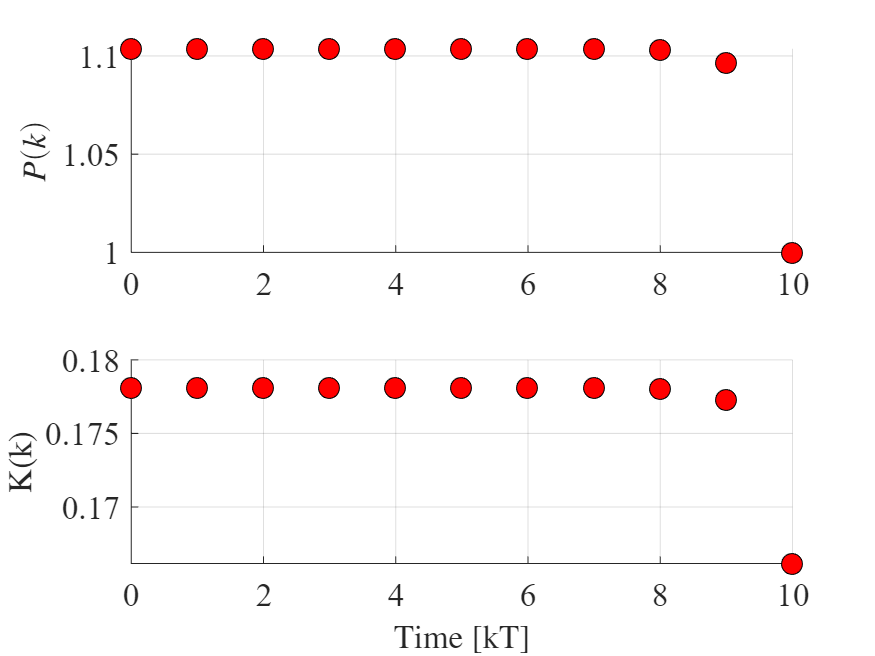

% Your solution goes here:
x(1)=1;
for i=1:10
   K(i) = (R2+G*P(i)*G)^-1*G*P(i)*F;
   u(i) = -K(i)*x(i);
   x(i+1) = F*x(i) + G*u(i);
end
i = 11;
K(i) = (R2+G*P(i)*G)^-1*G*P(i)*F;
u(i) = -K(i)*x(i);
%Plotting
figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
i = 0:10; 
% v = [0 9 1 1.2]; axis(v);
plot(i,P,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',10)
ylabel('$P(k)$','FontName','times','FontSize',16,'Interpreter','latex');

h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
% v = [0 9 0 0.2]; axis(v);
plot(i,K,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',10)
ylabel('K(k)','FontName','times','FontSize',16,'Interpreter','latex');
xlabel('Time [kT]','FontName','times','FontSize',16,'Interpreter','latex')

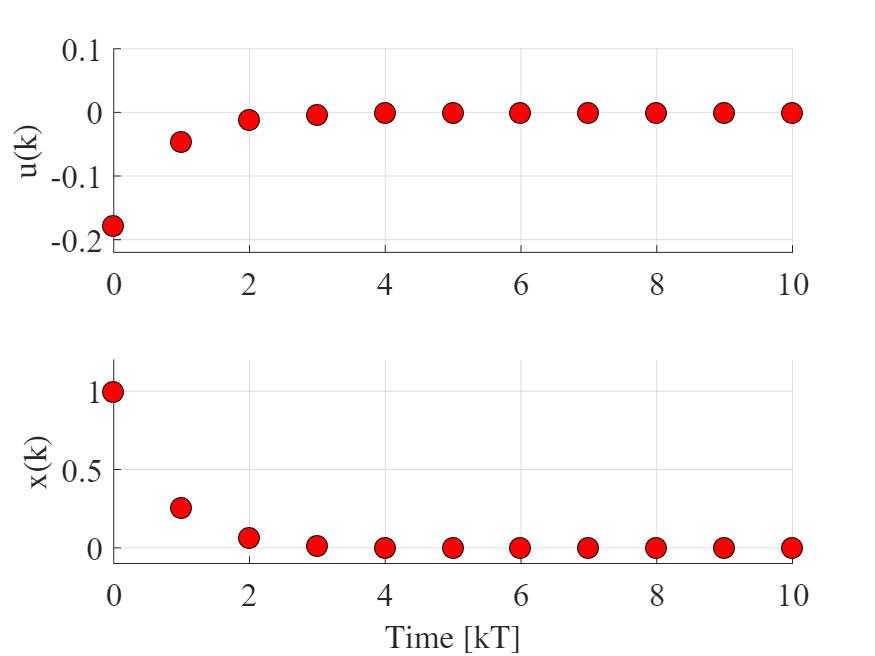

figure, h3 = subplot(2,1,1); set(h3,'FontName','times','FontSize',16)
hold on, grid on
v = [0 10 -0.22 0.1]; axis(v);
plot(i,u,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',10)
ylabel('u(k)','FontName','times','FontSize',16,'Interpreter','latex');

h4 = subplot(2,1,2); set(h4,'FontName','times','FontSize',16)
hold on, grid on
v = [0 10 -0.1 1.2]; axis(v);
plot(i,x,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',10)
ylabel('x(k)','FontName','times','FontSize',16,'Interpreter','latex');
xlabel('Time [kT]','FontName','times','FontSize',16,'Interpreter','latex')

**Problem 3 **What is the minimum value of the performance index $J_{\min}=\frac{1}{2}x^\text{T}(0)\mathbf{P}(0)x(0)$ ?

**Solution:**

% Your solution goes here:
Jmin = 0.5*x(1)'*P(1)*x(1);
disp('The minimum value of the performance index is'); disp(Jmin);

The minimum value of the performance index is
      0.55183



i = 10;
t=0;
for p=1:i
    t = t+x(p)^2+u(p)^2;
end
J = 0.5*x(11)^2+0.5*t

J =       0.55183


## **Part B - **An integral LQR Regulator for a Servo System.

It is desired to design a steady state optimal controller for the servo loop in the Figure below:

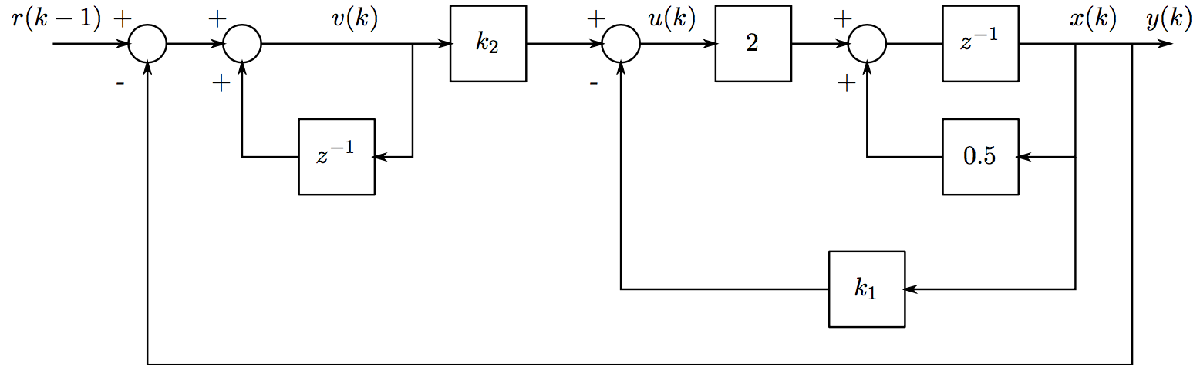

The sample period for the loop is $T=0.1 \mathrm{s}$. Clearly, $k_1$ is the integral gain and $k_2$ is the proportional gain.

**Problem 1**  Write down the state equations of the system, including the inputs and states. Show that the state equations of the system are:


$$\left[\matrix{ x(k+1) \cr v(k+1)}\right] = \left[\matrix{0.5 & 0 \cr -0.5 & 1}\right] \left[\matrix{ x(k) \cr v(k) }\right] + \left[\matrix{ 2 \cr -2}\right]u(k) + \left[\matrix{ 0 \cr 1 }\right] r(k)$$


**Solution:**

% Your solution goes here:
% Derive by hand and fill in using the equation editor, latex expressions, photo of handwriting or other means.



**Problem 2**  Write down the state equations for the system when $t\rightarrow \infty$. The reference input is to be held constant.

**Solution:**

% Your solution goes here:
% Derive by hand and fill in using the equation editor, latex expressions, photo of handwriting or other means.




**Problem 3**  Define the new incremental variables:


$$x_e(k) = x(k) - x(\infty) \\ v_e(k) = v(k) - v(\infty) \\ u_e(k) = u(k) - u(\infty)$$


Now write down the state equations of the system in terms of the new variables above. What is the new feedback law?

**Solution:**

% Your solution goes here:
% Derive by hand and fill in using the equation editor, latex expressions, photo of handwriting or other means.




**Problem 4**  Design a optimal steady state controller for the system above such that the performance index:


$$J = \frac{1}{2}\sum\limits_{k=0}^\infty \left[\left[\matrix{ x_e(k) \cr v_e(k) }\right]^\text{T} \mathbf{R}_1 \left[\matrix{ x_e(k) \cr v_e(k) }\right] + u_e^\text{T}(k) \mathbf{R}_2 u_e(k)\right]$$


is minimized where:


$$\mathbf{R}_1 = \left[\matrix{100 & 0 \cr 0 & 1}\right], \qquad \mathbf{R_2}=1$$


Find the optimal feedback gain matrix for the servo system.

**Solution:**

% Your solution goes here:
F = [0.5 0;-0.5 1];
G = [2;-2];
Gr = [0;1];
C = [1 0];
D = 0;

% weighting matrices
R1 = [100 0;0 1];
R2 = 1;

% lqr controller gain
% Method 1: dlqr()
[K,P,~] = dlqr(F,G,R1,R2)

K =     0.2494   -0.0475


P =   100.0624   -0.0119
   -0.0119   10.5168


% method 2: dare
P = dare(F,G,R1,R2)

P =   100.0624   -0.0119
   -0.0119   10.5168


K = inv(R2+G'*P*G)*G'*P*F

K =     0.2494   -0.0475


% method 3: iteration
P = [0 0;0 0];
P = R1 + F'*P*(eye(2)+G*R2^-1*G'*P)^-1*F;
for i=0:1000
    P = R1 + F'*P*(eye(2)+G*R2^-1*G'*P)^-1*F;
end
disp('Solution of the Riccati equation:'); disp(P);

Solution of the Riccati equation:
       100.06    -0.011872
    -0.011872       10.517



K = inv(R2+G'*P*G)*G'*P*F

K =     0.2494   -0.0475


**Problem 5**  Simulate the servo control system response to a step change in the reference input. Plot the input to the system on one plot and in two different plots below, the output of the integrator $v(k)$ and the system output $y(k)$. Explain your results.

**Solution:**

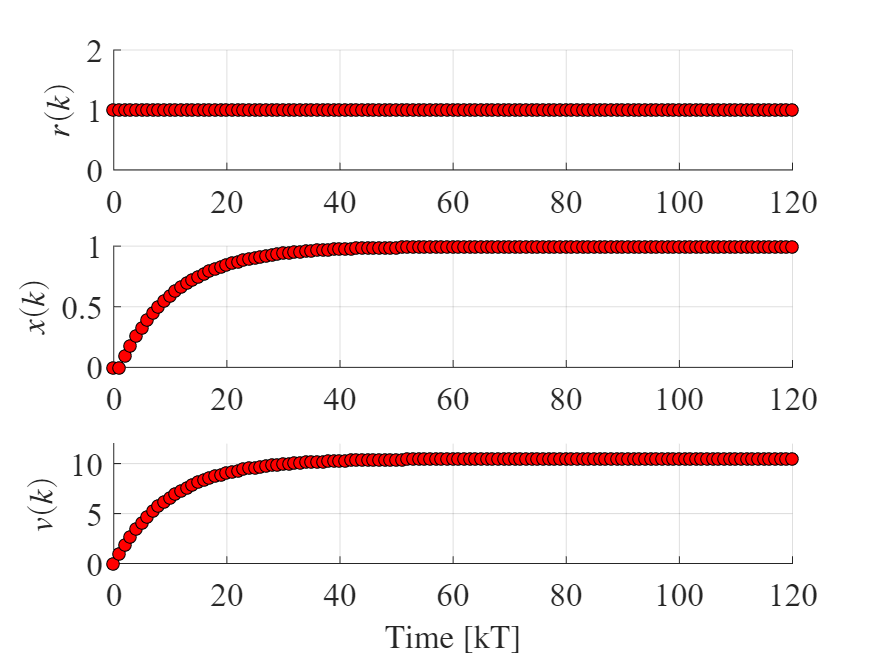

% Your solution goes here:
T = 0.1;

k = 0:120;
r = ones(1,length(k));
x = zeros(2,length(k));
u = ones(1,length(k));

for i=1:length(k)-1
    u(i) = -K*x(:,i);
    x(:,i+1) = F*x(:,i)+G*u(i)+Gr*r(i);
end
y = x(1,:);
v = x(2,:);

% Plotting
figure, h1 = subplot(3,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(k,r,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',6);
ylabel('$r(k)$','FontName','times','FontSize',16,'Interpreter','latex')

h2 = subplot(3,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(k,y,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',6);
ylabel('$x(k)$','FontName','times','FontSize',16,'Interpreter','latex')

h3 = subplot(3,1,3); set(h3,'FontName','times','FontSize',16)
hold on, grid on
plot(k,v,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',6);
ylabel('$v(k)$','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [kT]','FontName','times','FontSize',16,'Interpreter','latex')
ylim([0 12]);

% steady state of v
v(end)

ans =        10.517
